# Polinomios de interpolación en el análisis de temperatura

En primer lugar, se cargarán los datos de temperaturas durante todo el mes de noviembre en Cañete. Estas temperaturas fueron medidas una cada hora durante todo el mes.

TNov = readmatrix('noviembre.csv','Range','C12:C730')';
tNov = (0:1:length(TNov)-1); 

Ahora, se procederá a realizar una gráfica de los puntos de las temperaturas extraídas. Adicionalmente, se unirán estos puntos con la finalidad de encontrar alguna relación entre ellos.

GraficaGeneral(TNov, tNov); hold off;

Podemos observar que, cada 24 horas aproximadamente, exiten picos de temperaturas bastante pronunciados. Esto es debido a que por lo general durante la noche las temperaturas descienden y por la mañana esta aumenta.

Como los puntos mostrados anteriormente son muy variables, se decidió que el usuario indique una hora del día en específico a analizar durante todo el mes, para así realizar un análisis más completo respecto a una hora del día.

opcion = input('¿Usted tiene conocimiento del proyecto? Sí/No: ', 's');

if strcmp(opcion, 'Sí')
    hora = input("Ingresa la hora del día a analizar (0-23): ");
    grado = input("Ingresa el grado del polinomio aproximante: ");
else
    hora = 12;
    grado = 4;
    fprintf('Hora por defecto: %d\n', hora)
    fprintf('Grado de polinomio de mínimos cuadrados por defecto: %d\n', grado)
end

Se realiza la gráfica del spline cúbico natural y del polinomio de grado ingresado por el usuario. De esta manera, se puede apreciar de mejor manera el comportamiento de ambos métodos.

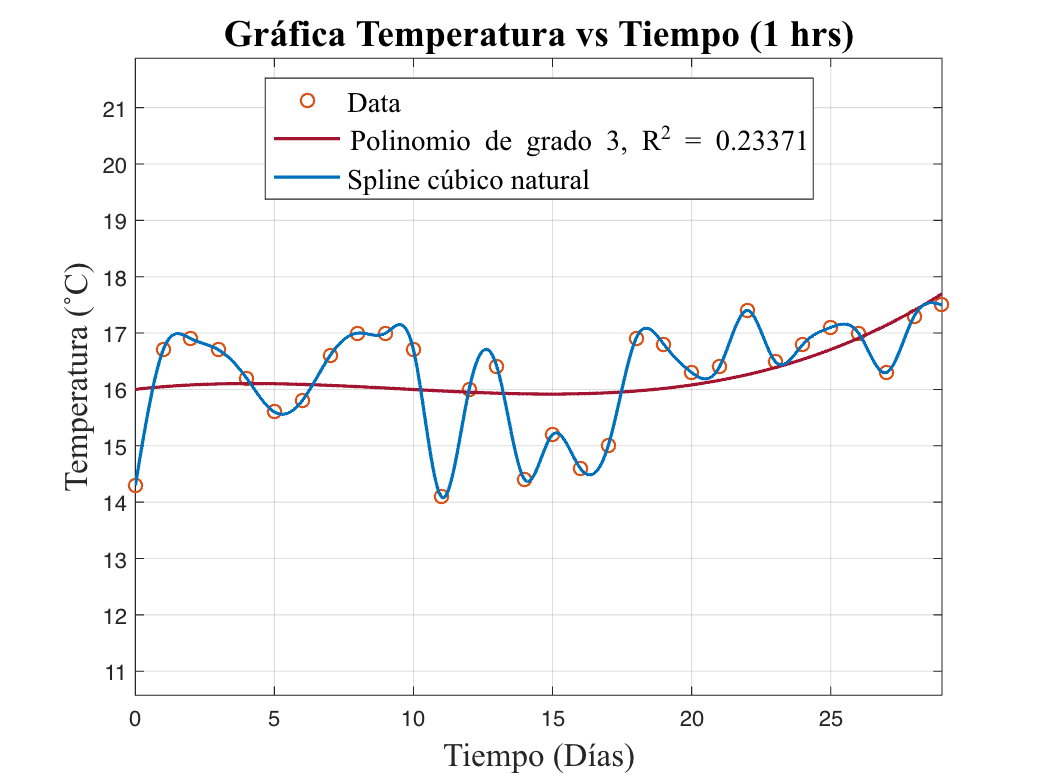

[tNovHora, TNovHora, Sx, P] = GraficaSpline(TNov, hora+1, grado);
hold off

Dependiendo de la hora del día que el usuario ingresó, el análisis será diferente. Sin embargo, en todos se puede apreciar que el spline es de mayor utilidad en el sentido que consigue pasar por todos los puntos.

### 
$$\textrm{Polinomio}\;\textrm{de}\;\textrm{Mínimos}\;\textrm{Cuadrados}:$$



$$P_4 \left(t\right)=\;$$


syms t

disp(poly2sym(round(vpa(P, 2), 8), t))

$$0.00446925\,t^{2}-0.09779517\,t+16.56354839$$

### 
$$\textrm{Spline}\;\textrm{Cúbico}\;\textrm{Natural}:$$


#### 
$$S_i \left(t\right)={a\left(t-t_i \right)}^3 +{b\left(t-t_i \right)}^2 +c\left(t-t_i \right)+d\;\;\forall \;\;\;\;i=0,1,\ldotp \ldotp \ldotp ,N-1$$


disp(Sx)

    i     (t-t[i])        a            b            c         d       [t(i), t(i+1)]  
    __    ________    _________    _________    _________    ____    _________________

     0    "(t-0)"      -0.56274            0       2.6627    14.7    "si t ∈ [0, 1]"  
     1    "(t-1)"        0.7137      -1.6882      0.97452    16.8    "si t ∈ [1, 2]"  
     2    "(t-2)"     -0.092055      0.45288     -0.26082    16.8    "si t ∈ [2, 3]"  
     3    "(t-3)"      -0.44548      0.17671      0.36877    16.9    "si t ∈ [3, 4]"  
     4    "(t-4)"       0.67397      -1.1597     -0.61425      17    "si t ∈ [4, 5]"  
     5    "(t-5)"     -0.050418       0.8622     -0.91178    15.9    "si t ∈ [5, 6]"  
     6    "(t-6)"       -0.3723      0.71094      0.66136    15.8

Graficamos el polinomio interpolante de Newton:

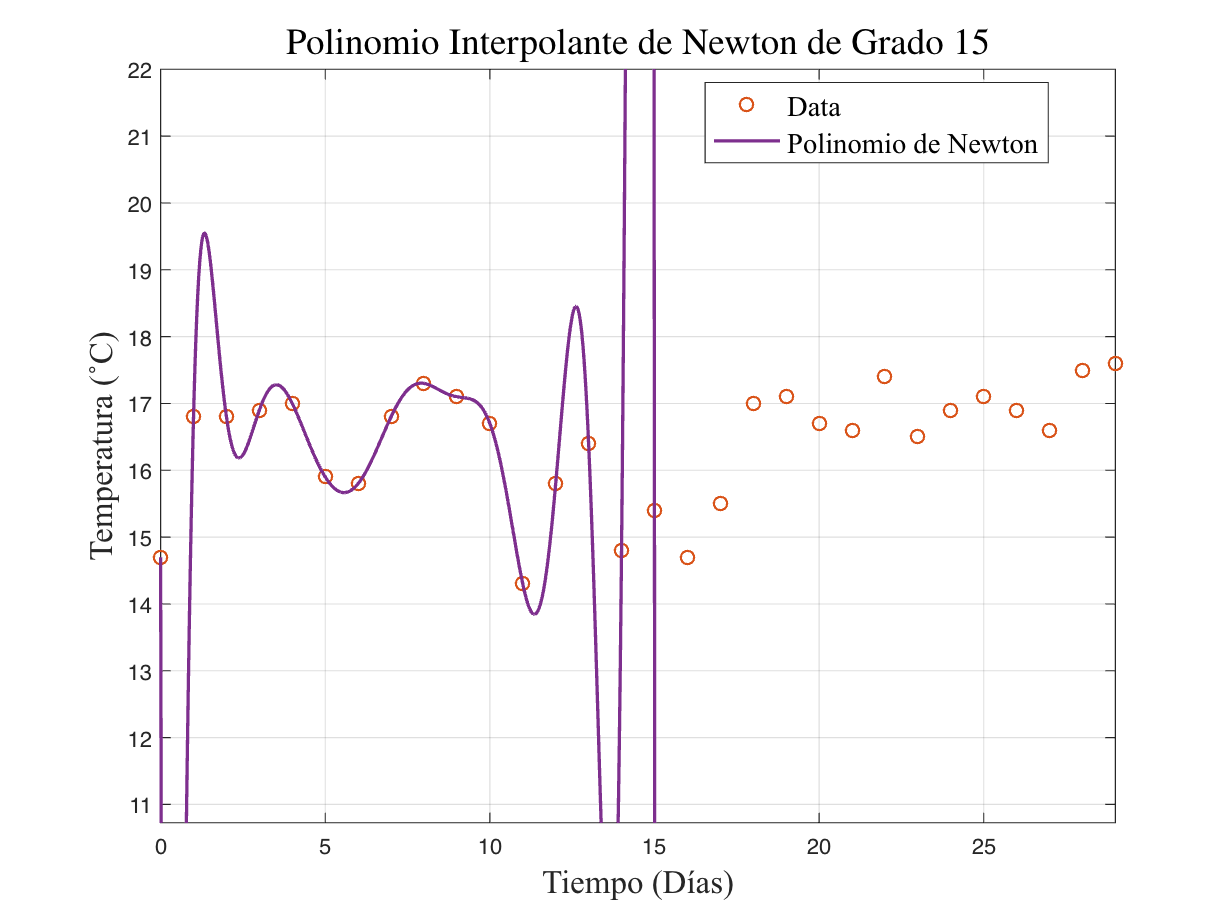

GraficaNewton(tNovHora, TNovHora, ceil(length(tNovHora)/2));

Se puede apreciar que el polinomio de interpolación de Newton mediante la fórmula de Newton es muy errático al intentar predecir temperaturas entre los puntos interpolados. A pesar de conseguir la interpolación, está lejos de ser un método eficiente de predicción al tener una gran cantidad de puntos.

Gráfica de aproximación de Temperatura para los primeros días de diciembre:

TDic = readmatrix('diciembre.csv','Range','C12:C263')';
TDicHora = TDic((hora+1):24:end);
[~, n] = size(TDicHora);

fprintf("Cantidad de Temperaturas reales de diciembre disponibles para las %d:00 hrs: %d", hora, n)

Cantidad de Temperaturas reales de diciembre disponibles para las 1:00 hrs: 11

while true
    cant_dias = input("Ingrese la cantidad [c] de días de diciembre para estimar (c<=" +int2str(n) + "): ");
    if cant_dias <= n
        break
    end
end

Se predecirán las temperaturas del mes de diciembre haciendo uso del polinomio de mínimos cuadrados del mes de noviembre.

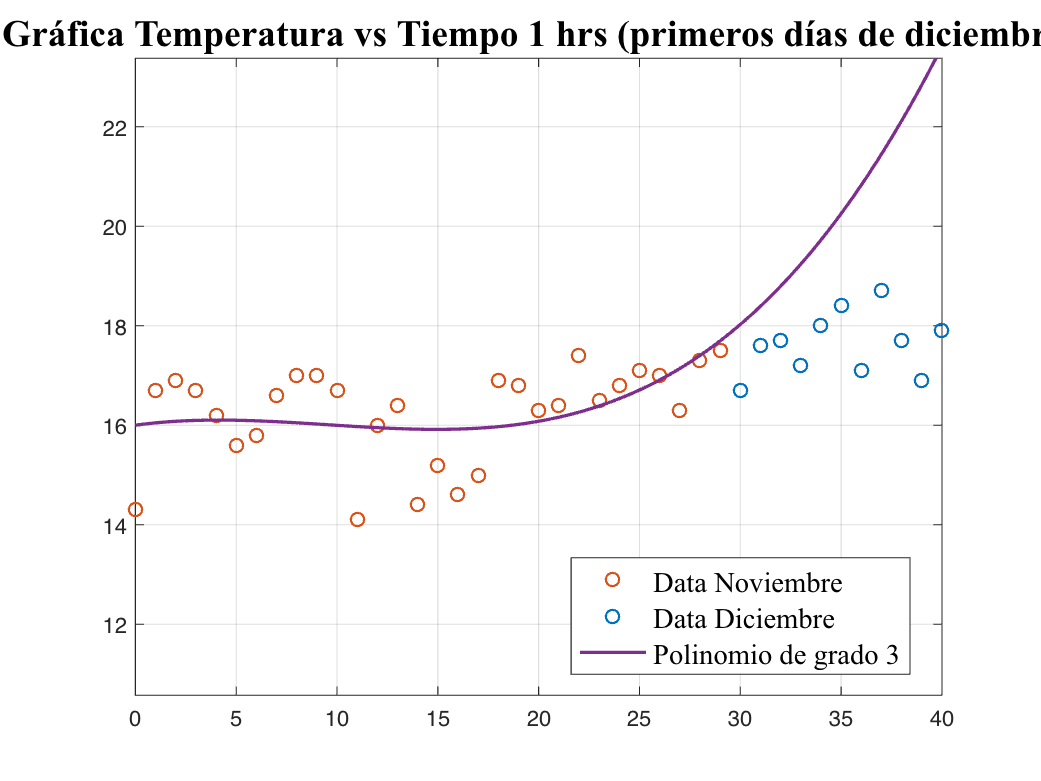

GraficaConDiciembre(TNovHora, TDicHora(1, 1:cant_dias), hora+1, P, grado, cant_dias);

Taprox = polyval(P, (30:1:(29+cant_dias)));
Treal = TDicHora(1:cant_dias);
Error_absoluto = abs(Treal - Taprox);
disp("Error absoluto de las aproximaciones realizadas para el mes de Diciembre en orden diario"); disp(Error_absoluto);

Error absoluto de las aproximaciones realizadas para el mes de Diciembre en orden diario
    0.7520    0.3268    0.3106    0.9033    0.4050    0.2156    1.5351    0.1635    1.4009    2.4473    1.6025



fprintf("Norma euclidiana (2) del error absoluto de las aproximaciones de Temperatura: %f", norm(Error_absoluto, 2))

Norma euclidiana (2) del error absoluto de las aproximaciones de Temperatura: 3.833845

Error_relativo = Error_absoluto./Treal;
disp("Error relativo de las aproximaciones realizadas para el mes de Diciembre en orden diario"); disp(Error_relativo);

Error relativo de las aproximaciones realizadas para el mes de Diciembre en orden diario
    0.0445    0.0187    0.0175    0.0522    0.0225    0.0117    0.0887    0.0087    0.0783    0.1431    0.0881



fprintf("Norma euclidiana (2) del error relativo de las aproximaciones de Temperatura: %f", norm(Error_relativo, 2))

Norma euclidiana (2) del error relativo de las aproximaciones de Temperatura: 0.219808